clc
clear
load("DataAndVariables\BaseDefinitions.mat")
load("DataAndVariables\AvgValues.mat");
addpath("Functions\")

measuremedOutputs = [Psch(2:end,:) ; Qsch(2:end,:)];
p = 3;
n = 14;
m = n;

## Jacobian and sensitivity

delta = [0, V0(1:14).']; % voltage phase angle (initialise to slack bus, if possible)
V = [1, V0(15:end).']; % voltage magnitude (initialise to slack bus, if possible)
[J, Sensitivity] = CalculateJacobian(Y,V,delta);

## Linear model

A = eye(nrBus-1);
B = Sensitivity(15:28,[15, 21, 24]);
C = eye(nrBus-1);
Cz = C;

## Step

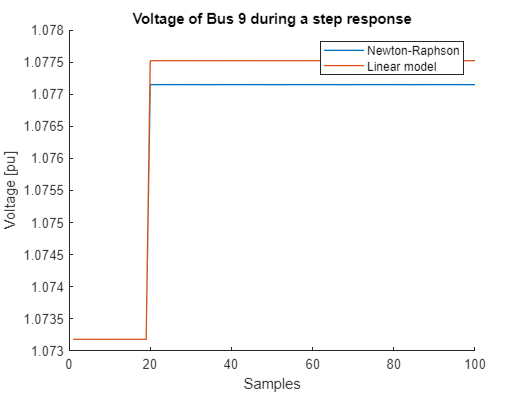

samples = 100;
step = ones(3,1);

Vrap = zeros(14,samples);
Vlin = zeros(14,samples);
[Vout, Sout] = NewRap(measuremedOutputs(:,1));
Vrap(:,1) = Vout(15:end);
Vlin(:,1) = Vout(15:end);
for i=2:samples
    if (i == 20)
        updatedPower = Sout;
        updatedPower([15, 21, 24]) = updatedPower([15, 21, 24]) + step;
        [Vout, Sout] = NewRap(updatedPower);
        Vrap(:,i) = Vout(15:end);
        Vlin(:,i) = A * Vlin(:,i-1) + B*step;
    else
        [Vout, Sout] = NewRap(Sout);
        Vrap(:,i) = Vout(15:end);
        Vlin(:,i) = A * Vlin(:,i-1) + B*zeros(3,1);
    end
end
figure()
hold on
plot(Vrap(9,:),LineWidth=1)
plot(Vlin(9,:),LineWidth=1)
hold off
legend("Newton-Raphson","Linear model")
ylabel("Voltage [pu]")
xlabel("Samples")
title("Voltage of Bus 9 during a step response")

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/StepResponse','epsc')